syms m1 I1 r m2 I2 g real 
syms h
syms theta(t) phi(t) dtheta dphi
syms x1 y1 dx1 dy1 x2 y2 dx2 dy2 real

d_theta = diff(theta,t);
d_phi = diff(phi,t);
wheel_ts_vel = dx2 == r*(d_theta+d_phi) ;
car_vel_x=dx1==dx2+h*d_theta*cos(theta);
car_vel_x_2=subs(car_vel_x,dx2,rhs(wheel_ts_vel));
car_vel_y = dy1==-h*d_theta*sin(theta);
KE_TS= 1/2 * m1 * (h^2 * (d_theta)^2 + 2*h*r*cos(theta)*d_phi*d_theta+2*h*r*cos(theta)*(d_theta)^2+r^2*(d_phi)^2+2*r^2*d_phi*d_theta+r^2*(d_theta)^2) + 1/2 * m2 * (rhs(wheel_ts_vel)^2);
KE_RT= 1/2 * I1*(d_theta)^2 + 1/2 * I2* (d_phi+d_theta)^2;
KE_TOTAL = KE_RT+KE_TS;
U=m1*g*(r+h*cos(theta));
L=KE_TOTAL-U

$$L(t) = \begin{array}{l} \frac{m_{1}\,\left(h^{2}\,\sigma_{1}+r^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+r^{2}\,\sigma_{1}+2\,r^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+2\,h\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+2\,h\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}{2}+\frac{I_{1}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{2}}{2}-g\,m_{1}\,\left(r+h\,\cos\left(\theta \left(t\right)\right)\right)+\frac{m_{2}\,r^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\varphi \left(t\right)+\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

dL_ddtheta = diff(L,d_theta);
dblah_dt=diff(dL_ddtheta,t);
dL_dtheta = diff(L,theta);
eqn_of_motion=dblah_dt-dL_dtheta==0

$$eqn\_of\_motion(t) = \begin{array}{l} \frac{I_{2}\,\sigma_{3}}{2}+\frac{m_{1}\,\left(2\,h^{2}\,\sigma_{4}+2\,r^{2}\,\sigma_{5}+2\,r^{2}\,\sigma_{4}-4\,h\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+2\,h\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{5}+4\,h\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{4}-\sigma_{1}\right)}{2}+I_{1}\,\sigma_{4}+\frac{m_{1}\,\left(2\,h\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+\sigma_{1}\right)}{2}+\frac{m_{2}\,r^{2}\,\sigma_{3}}{2}-g\,h\,m_{1}\,\sin\left(\theta \left(t\right)\right)=0\\ \mathrm{where}\\ \sigma_{1}=2\,h\,r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=2\,\sigma_{5}+2\,\sigma_{4}\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{5}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

eq_theta_approx = subs(eqn_of_motion,sin(theta),theta);
eq_theta_approx_2 = subs(eq_theta_approx,cos(theta),1);
eq_final=subs(eq_theta_approx_2,(d_theta)^2,0);
eq_final_t=simplify(eq_final);
eq_final_2 = lhs(eq_final_t)-rhs(eq_final_t) 

$$eq\_final\_2(t) = \begin{array}{l} I_{2}\,\sigma_{2}+I_{1}\,\sigma_{1}+I_{2}\,\sigma_{1}+h^{2}\,m_{1}\,\sigma_{1}+m_{1}\,r^{2}\,\sigma_{2}+m_{2}\,r^{2}\,\sigma_{2}+m_{1}\,r^{2}\,\sigma_{1}+m_{2}\,r^{2}\,\sigma_{1}-g\,h\,m_{1}\,\theta \left(t\right)+h\,m_{1}\,r\,\sigma_{2}+2\,h\,m_{1}\,r\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

dd_phi = diff(d_phi,t);
dd_theta = diff(d_theta,t);
ref=[theta,d_theta,d_phi];
u=dd_phi;
A=jacobian(eq_final_2,ref)

$$A(t) = \left(\begin{array}{ccc} -g\,h\,m_{1} & 0 & 0 \end{array}\right)$$

B=jacobian(eq_final_2,u)

$$B(t) = I_{2}+m_{1}\,r^{2}+m_{2}\,r^{2}+h\,m_{1}\,r$$

a = g*h*m1/(I1+I2+h^2*m1+2*h*m1*r+m1*r^2+m2*r^2);
b= (-I2-h*m1*r-m1*r^2-m2*r^2)/(I1+I2+h^2*m1+2*h*m1*r+m1*r^2+m2*r^2);
A = [0 1 0; a 0 0;0 0 0];
B=[0;b;1];
A_sim=double(subs(A,{m1,I1,r,m2,I2,h,g},{0.3,7,0.06,0.03,1.5,0.07,9.81}))

A_sim =          0    1.0000         0
    0.0242         0         0
         0         0         0


B_sim=double(subs(B,{m1,I1,r,m2,I2,h,g},{0.3,7,0.06,0.03,1.5,0.07,9.81}))

B_sim =          0
   -0.1767
    1.0000


C=ctrb(A_sim,B_sim)

C =          0   -0.1767         0
   -0.1767         0   -0.0043
    1.0000         0         0


D_sim = zeros(size(B_sim));
rank(C)

ans = 3

Q=[10000 0 0;0 1 0; 0 0 0.01];
R=0.03;
K=lqr(A_sim,B_sim,Q,R)

K =  -577.4990  -84.3998   -0.5774


ss_eqn=A_sim-B_sim*K;
tspan=0:0.01:2;
x0=[pi/4;0;0];
xf =[0;0;0]; 
odefunc = @(t,x)ss_eqn*(x-xf);
[t,x]=ode45(odefunc,tspan,x0);
% 
x_dev = x - xf';
size(x)

ans =    201     3


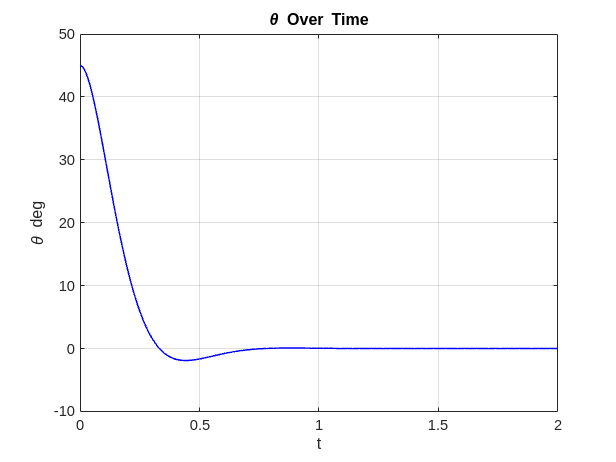

% Figure 1: \theta Over Time
figure;
plot(t, x(:,1)*57.3, 'b', 'LineWidth', 1);
xlabel('t');
ylabel('\theta deg');
title('\theta Over Time');
grid on;

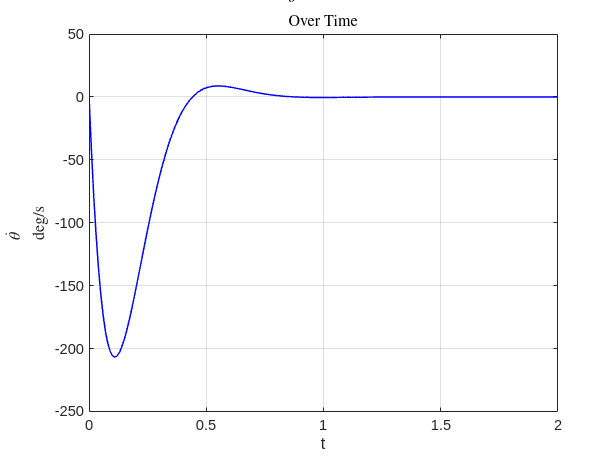


% Figure 2: \dot{\theta} Over Time
figure;
plot(t, x(:,2)*57.3, 'b', 'LineWidth', 1);
xlabel('t');
ylabel(['$$\dot{\theta}$$ deg/s'], 'Interpreter', 'latex');
title(['$$\dot{\theta}$$ Over Time'], 'Interpreter', 'latex');
grid on;

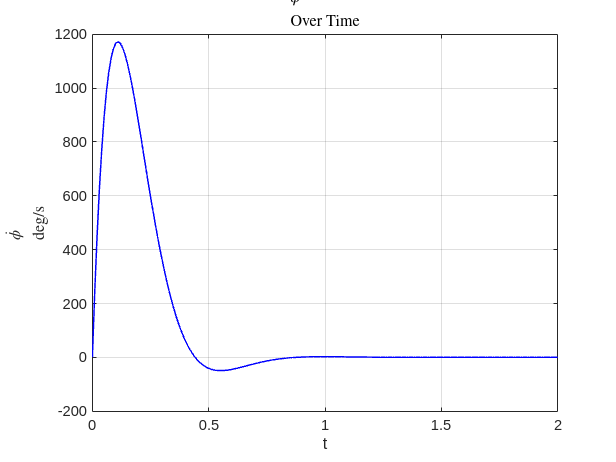


% Figure 3: \dot{\phi} Over Time
figure;
plot(t, x(:,3)*57.3, 'b', 'LineWidth', 1);
xlabel('t');
ylabel(['$$\dot{\phi}$$ deg/s'], 'Interpreter', 'latex');
title(['$$\dot{\phi}$$ Over Time'], 'Interpreter', 'latex');
grid on;

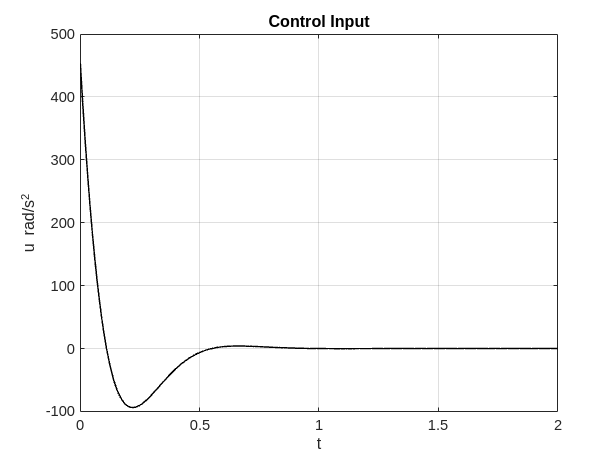


% Figure 4: Control Input
figure;
u1 = -K*x';
plot(t, u1, 'k', 'LineWidth', 1);
xlabel('t');
ylabel('u rad/s^2');
title('Control Input');
grid on;

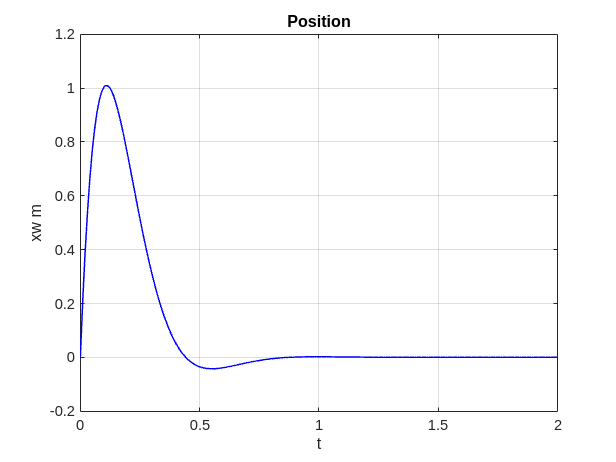


% Figure 5: Position
figure;
plot(t, 0.06*(x(:,2) + x(:,3)), 'b', 'LineWidth', 1);
xlabel('t');
ylabel('xw m');
title('Position');
grid on;



disp('Final state:');

Final state:


disp(x(end, :)');

   -0.0000
   -0.0000
    0.0152



disp('Desired final state:');

Desired final state:


disp(xf)

     0
     0
     0



%lsim(ss_eqn,u1,tspan,x0)
size(tspan )

ans =      1   201


length(u1)

ans = 201

size(u1)

ans =      1   201


sys= ss(A_sim,B_sim,C,D_sim);
UU=zeros(size(tspan));
[X]=lsim(ss_eqn,B_sim,C,D_sim,UU,tspan,x0)

X =          0   -0.1387    0.7854
    0.1316   -0.1561    0.7816
    0.2444   -0.1697    0.7709
    0.3398   -0.1798    0.7542
    0.4192   -0.1869    0.7327
    0.4841   -0.1913    0.7070
    0.5357   -0.1933    0.6781
    0.5753   -0.1931    0.6466
    0.6042   -0.1912    0.6132
    0.6235   -0.1877    0.5784


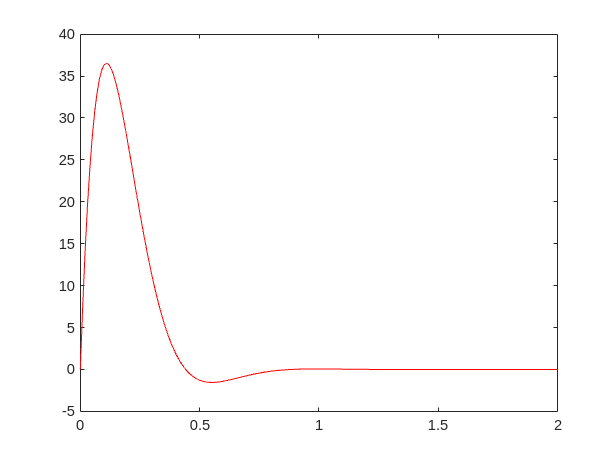

plot(tspan, X(:,1)*57.3, 'r')

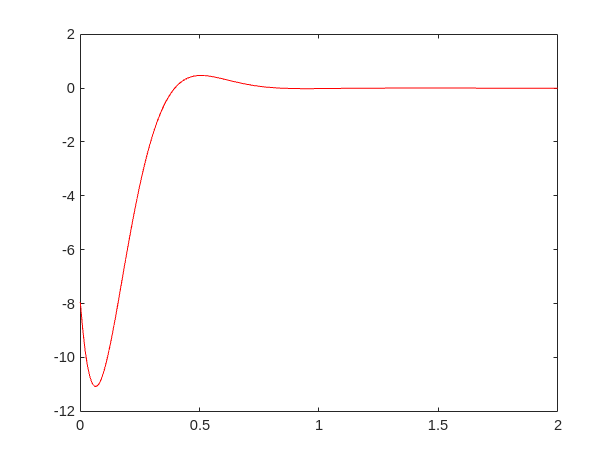

plot(tspan, X(:,2)*57.3, 'r')

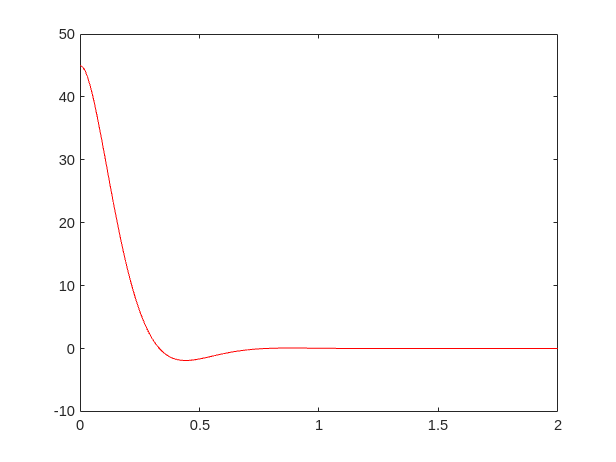

plot(tspan, X(:,3)*57.3, 'r')

plot(tspan, Y(:,1)*57.3, 'r')

Unrecognized function or variable 'Y'.

plot(tspan, Y(:,2)*57.3, 'r')
plot(tspan, Y(:,3)*57.3, 'r')